# Drilling & Welding

## Setup

clear;
close all;
clf
load('F_V_cylinder.mat');

### Plot the robot to initial position

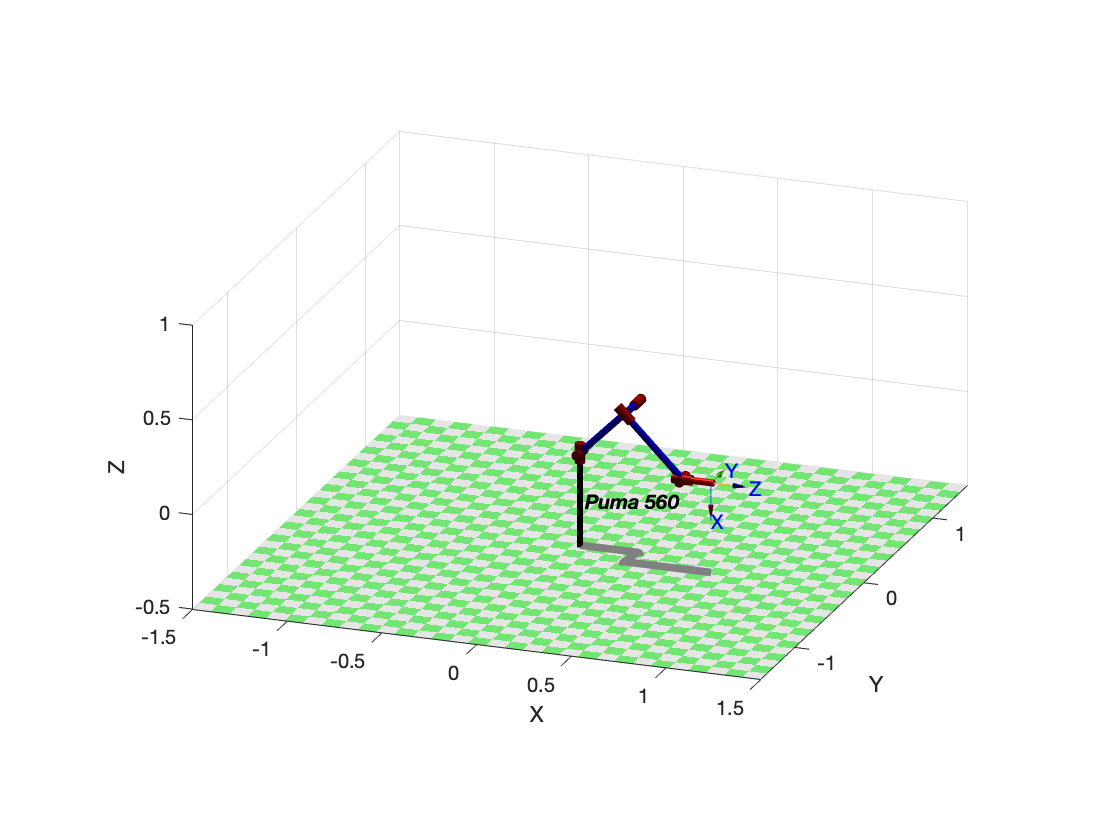

radius=0.20;
mdl_puma560;
p560.base = transl(0, 0, 0);
p560.tool=transl(0,0,0.15);
p560.plot(qn,'zoom',2.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],'view',[20 20] );
hold on

### Visualize cylinders

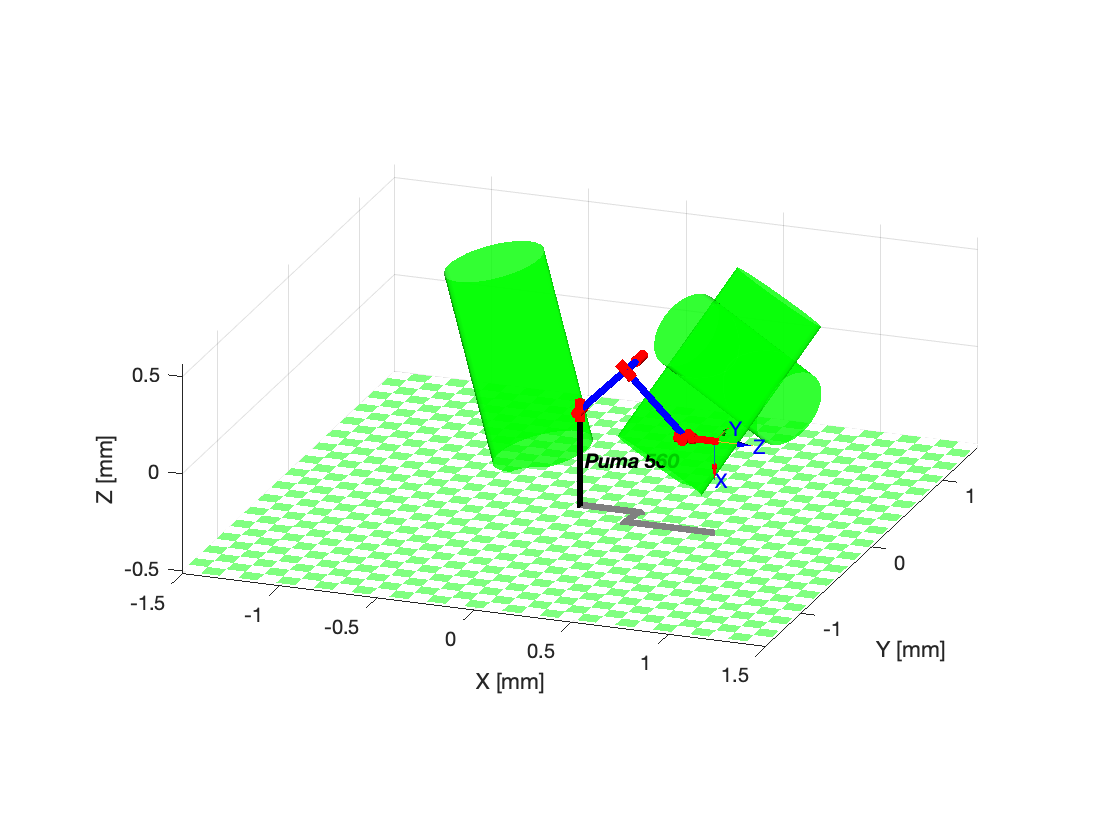

Cy_scale = 0.25;
weld_scale = 0.2;

left_cylinder_pose = transl([-0.3 0.3 -0.35]) * troty(-pi/6) * trotx(-pi/6);
V_left_cylinder_drill = left_cylinder_pose * [Cy_scale .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy,V_left_cylinder_drill(1:3,:)',[0 1 0])

right_cylinder_pose = transl([0.3 0.3 -0.35]) * troty(pi/6) * trotx(-pi/6);
V_right_cylinder_drill = right_cylinder_pose * [Cy_scale .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy,V_right_cylinder_drill(1:3,:)',[0 1 0])

welded_cylinder_pose = right_cylinder_pose * transl(0,0,0.6) * trotx(-pi/2) * troty(pi/4) * transl(0,0,-0.35);
V_welded_cylinder_drill = welded_cylinder_pose * [weld_scale .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy,V_welded_cylinder_drill(1:3,:)',[0 1 0])

## Drilling Task

### Draw drill task profile

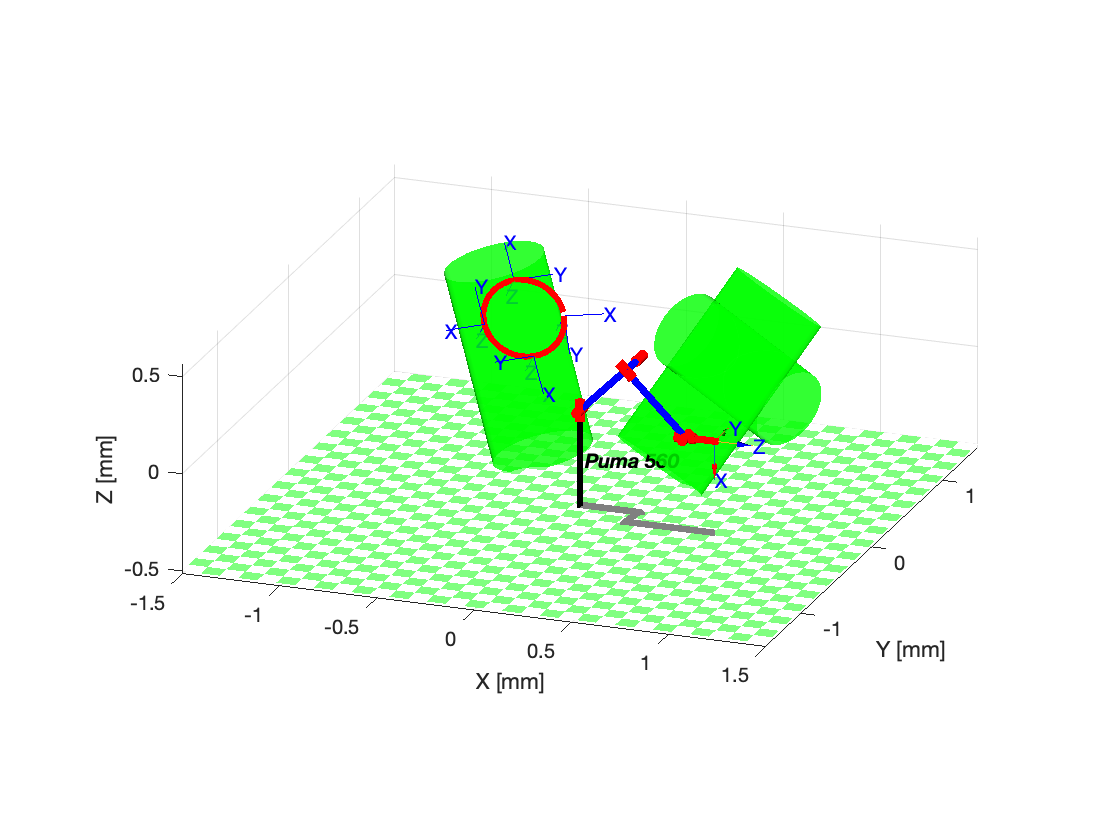

D_h_c = left_cylinder_pose * transl(0,0,0.6) * trotx(-pi/2) * troty(-pi/4) * transl(0,0,-0.25);

n = 60;
for i=1:n
Drill_Pose(:,:,i) = D_h_c * trotz(2*pi*i/n) * transl(radius, 0,0);
end

cir = transl(Drill_Pose)';

hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3)
axis equal
trplot(Drill_Pose(:,:,1), 'length',0.2)
trplot(Drill_Pose(:,:,15), 'length',0.2)
trplot(Drill_Pose(:,:,30), 'length',0.2)
trplot(Drill_Pose(:,:,45), 'length',0.2)

### Execute drilling

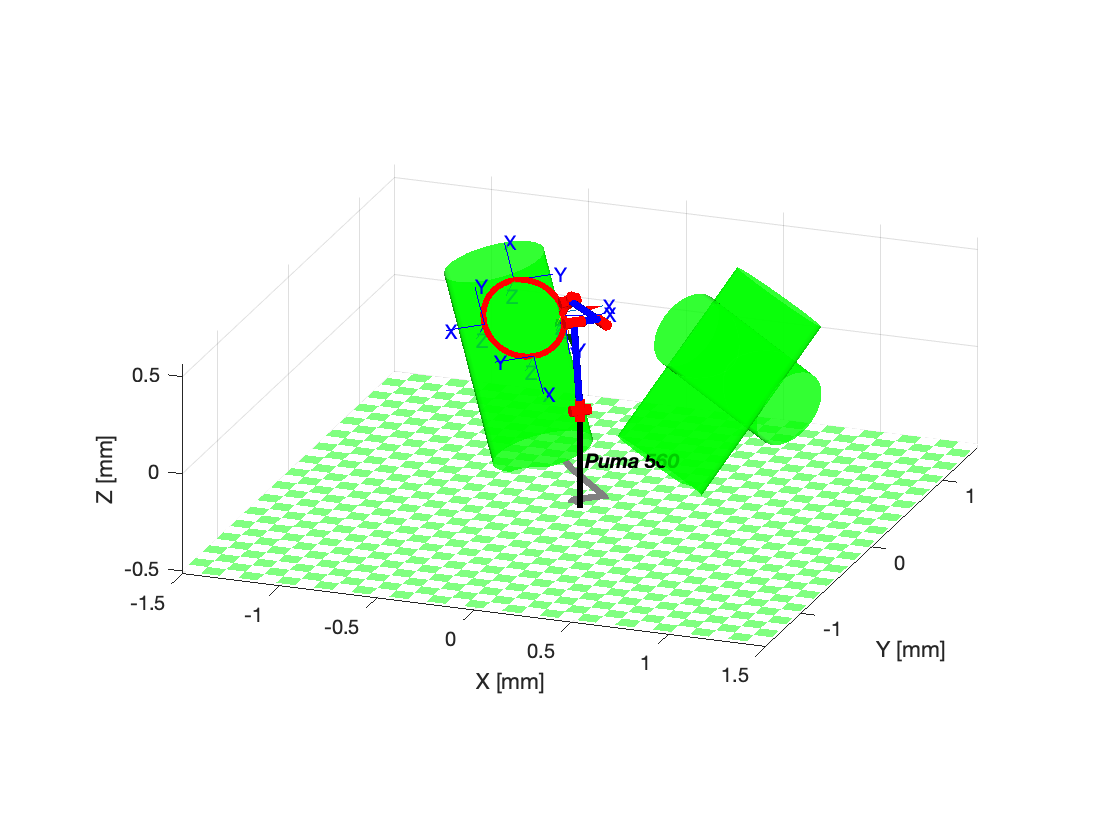

Q = p560.ikine6s(Drill_Pose, 'run');
p560.plot(Q,'view',[20 20], 'zoom',1.5,'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1],...
    'trail','-','jaxes','zoom',2)%, 'movie', 'drilling_task.mp4')

## Welding Task

### Draw weld task profile

### Execute welding

## Functions

function T_b_a = FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end